%pqr - roll pitch yaw
ATT(:,4), ATT(:,6), ATT(:,8)

ans =     2.2100
    2.2300
    2.2400
    2.2500
    2.3200
    2.3500
    2.3500
    2.3300
    2.2900
    2.2400


ans =    -3.5500
   -3.4500
   -3.3800
   -3.3400
   -3.2100
   -3.1300
   -3.0700
   -3.0200
   -2.9100
   -2.7600


ans =   193.0600
  192.9900
  192.9500
  192.8900
  192.7100
  192.6800
  192.6600
  192.6500
  192.6300
  192.6300


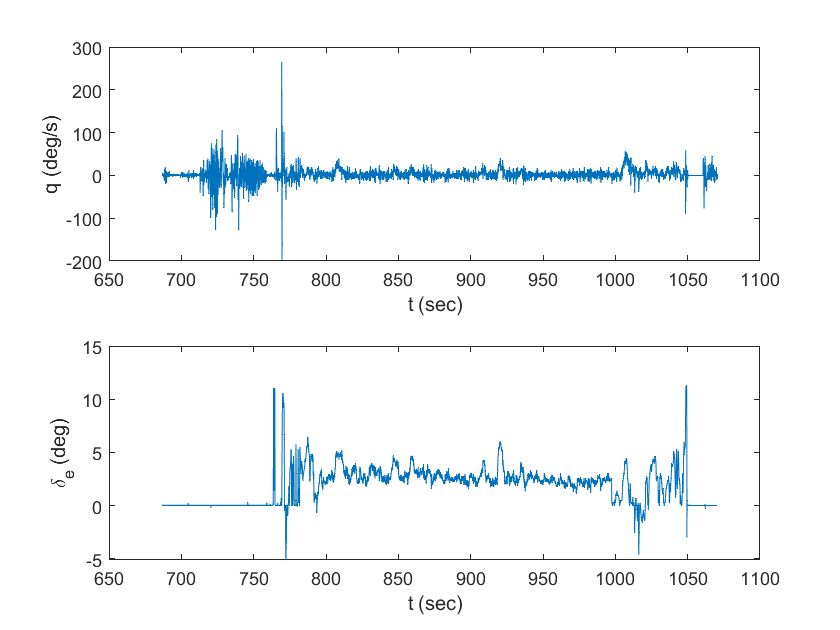


figure, subplot(2,1,1),plot(IMU(:,2)*1e-6,IMU(:,4)*180/pi), xlabel('t (sec)'), ylabel('q (deg/s)');
subplot(2,1,2),plot(AETR(:,2)*1e-6,AETR(:,4)*0.0025), xlabel('t (sec)'), ylabel('\delta_e (deg)');

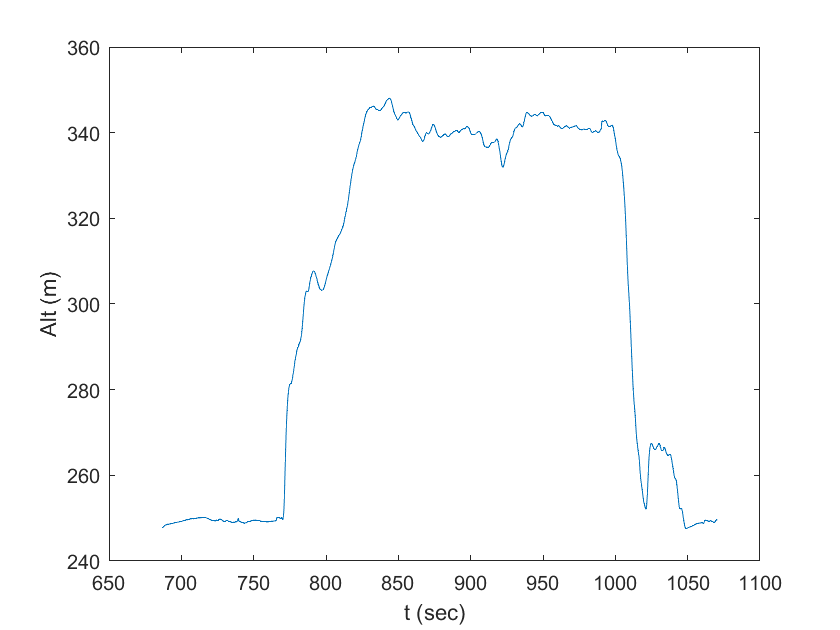



figure, plot(GPS(:,2)*1e-6,GPS(:,10)); xlabel('t (sec)'), ylabel('Alt (m)');

## plot full flight

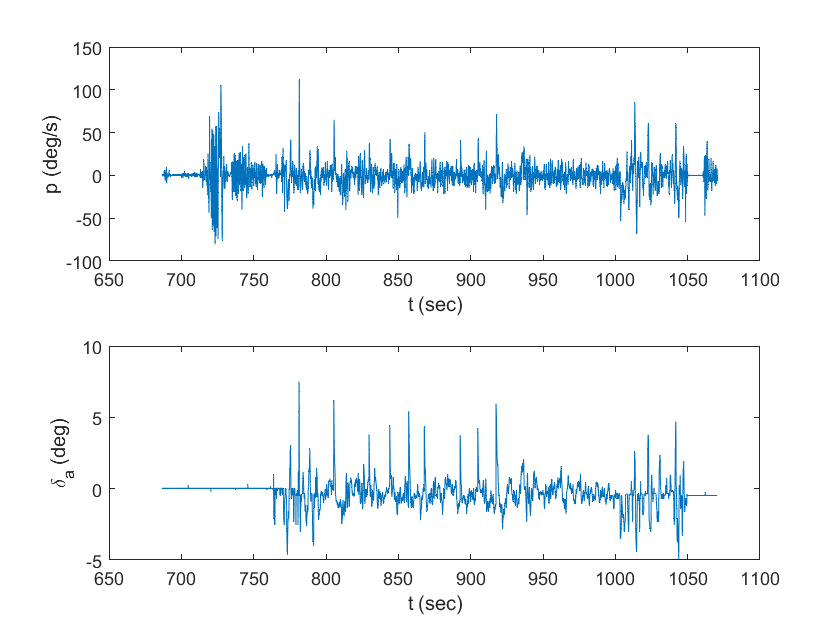


%p
figure, subplot(2,1,1),plot(IMU(:,2)*1e-6,IMU(:,3)*180/pi), xlabel('t (sec)'), ylabel('p (deg/s)');
subplot(2,1,2),plot(AETR(:,2)*1e-6,AETR(:,3)*0.0025), xlabel('t (sec)'), ylabel('\delta_a (deg)');

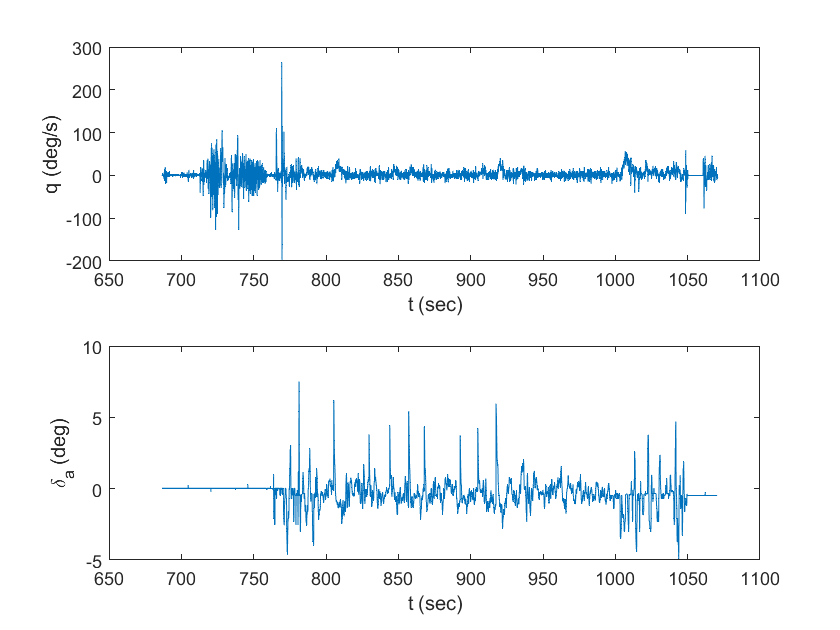


%q
figure, subplot(2,1,1),plot(IMU(:,2)*1e-6,IMU(:,4)*180/pi), xlabel('t (sec)'), ylabel('q (deg/s)');
subplot(2,1,2),plot(AETR(:,2)*1e-6,AETR(:,3)*0.0025), xlabel('t (sec)'), ylabel('\delta_a (deg)');

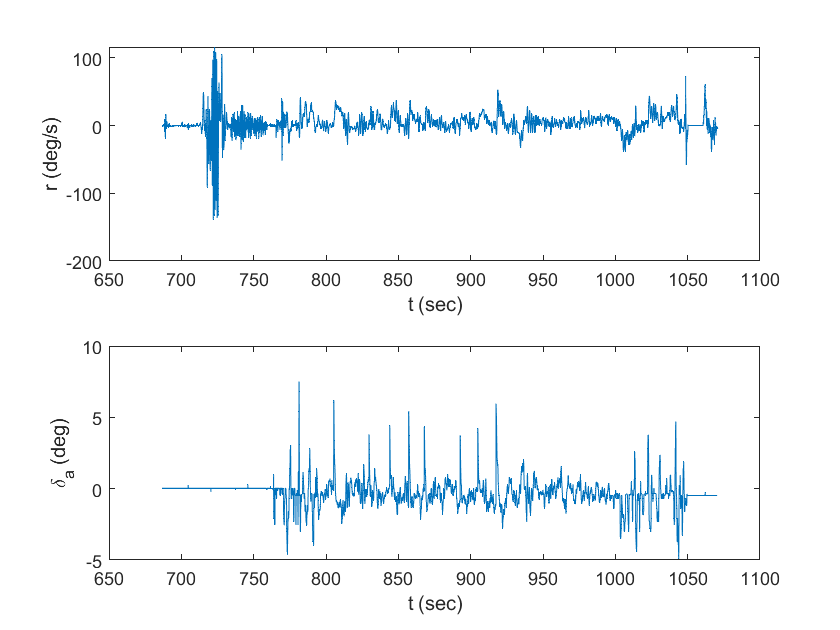


%r
figure, subplot(2,1,1),plot(IMU(:,2)*1e-6,IMU(:,5)*180/pi), xlabel('t (sec)'), ylabel('r (deg/s)');
subplot(2,1,2),plot(AETR(:,2)*1e-6,AETR(:,3)*0.0025), xlabel('t (sec)'), ylabel('\delta_a (deg)');

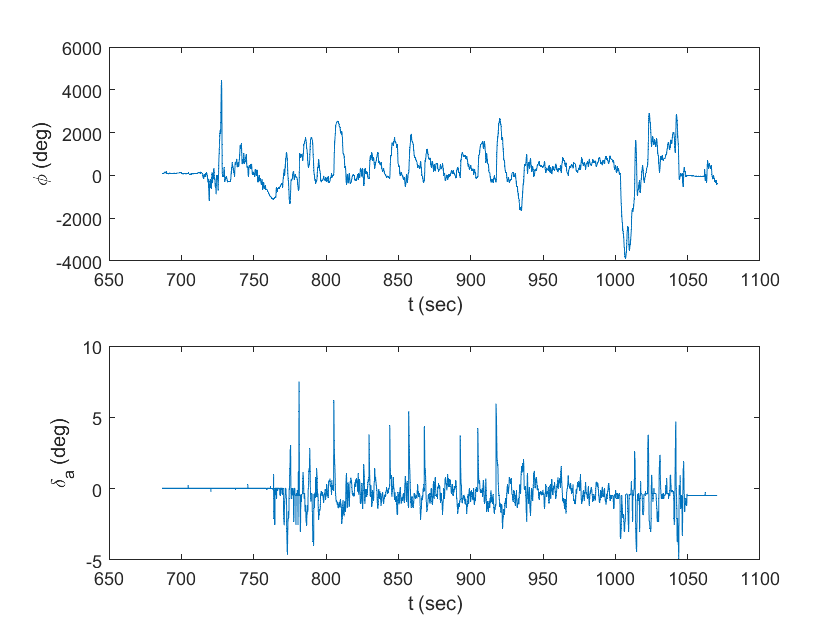


%q
figure, subplot(2,1,1),plot(AHR2(:,2)*1e-6,AHR2(:,3)*180/pi), xlabel('t (sec)'), ylabel('\phi (deg)');
subplot(2,1,2),plot(AETR(:,2)*1e-6,AETR(:,3)*0.0025), xlabel('t (sec)'), ylabel('\delta_a (deg)');

## plot short bit

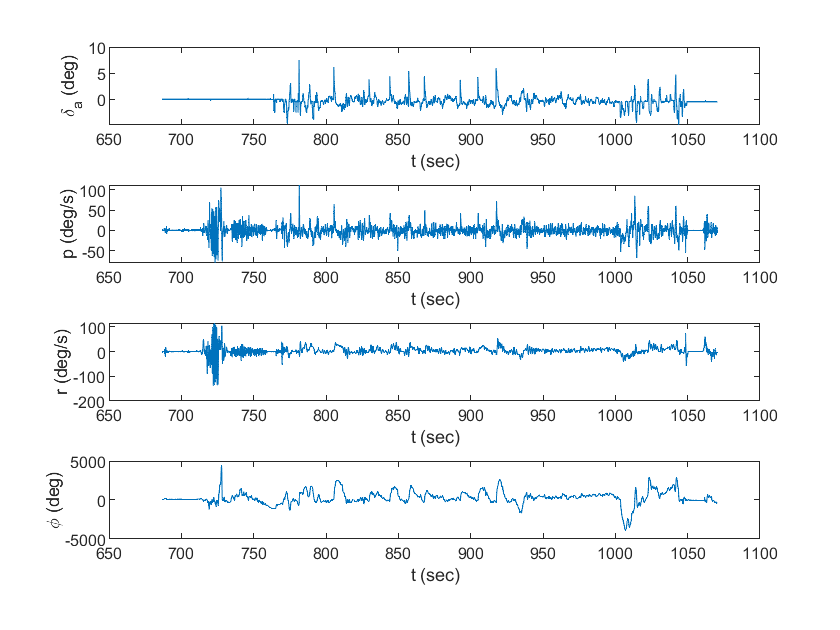

% t move = 905
% t start = 903
% t end = 908

t_start = 903;
t_end = 908;

%IMU(:,2) %find nearst in time for imu ans for aetr

%p
figure, subplot(4,1,1),plot(AETR(:,2)*1e-6,AETR(:,3)*0.0025), xlabel('t (sec)'), ylabel('\delta_a (deg)');
%p
subplot(4,1,2),plot(IMU(:,2)*1e-6,IMU(:,3)*180/pi), xlabel('t (sec)'), ylabel('p (deg/s)');
%r
subplot(4,1,3),plot(IMU(:,2)*1e-6,IMU(:,5)*180/pi), xlabel('t (sec)'), ylabel('r (deg/s)');
%q
subplot(4,1,4),plot(AHR2(:,2)*1e-6,AHR2(:,3)*180/pi), xlabel('t (sec)'), ylabel('\phi (deg)');